# Understanding the Vibration and Electrical Signals Dataset

This tutorial focuses on detecting failures in an AC induction motor. Typically, AC motors are driven by a three-phase power converter or an industrial power supply. Failures in the rotor bars of the motor can present themselves in various electrical and vibration signals collected from the system, including voltages and currents of each of the three phases and the acceleration and velocity signals in radial, axial, and tangential directions. Here, you use some of these signals in the **Diagnostic Feature Designer** app to extract features, which you then use to identify the number of broken rotor bars in the motor.

## Data Set

The experimental workbench consists of a three-phase induction motor coupled with a direct-current machine, which works as a generator simulating the load torque, connected by a shaft containing a rotating torque meter. For more details about the workbench setup, see [IEEE Broken Rotor Bar Database](https://ieee-dataport.org/open-access/experimental-database-detecting-and-diagnosing-rotor-broken-bar-three-phase-induction).

The data set contains electrical and mechanical signals from experiments on three-phase induction motors, using the experimental setup shown in the figure.

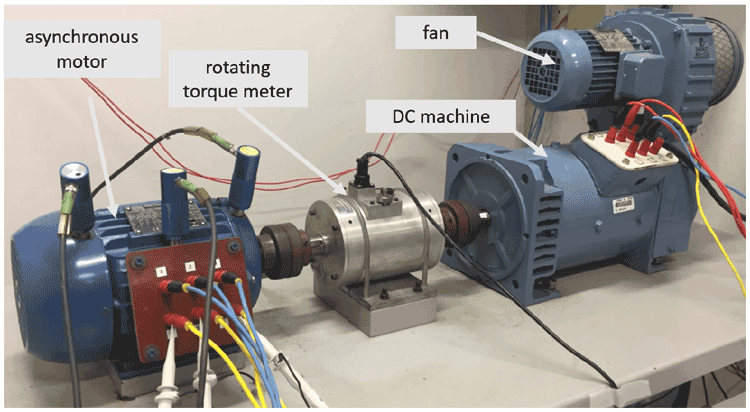

Electrical and vibration signals were collected from the system under the following health and loading conditions:

- 0, 1, 2, 3, and 4 broken rotor bars as the health condition

- 0.5, 1.0, 1.5, 2.0, 2.5, 3.0, 3.5, and 4.0 Nm torque as the load condition

Ten experiments were performed for each combination of health and loading condition. The following signals were acquired during each experiment:

- Voltage of each phase ($V_a$, $V_b$, $V_c$)

- Current draw of each phase ($I_a$, $I_b$, $I_c$)

- Mechanical vibration speeds tangential to the housing (${\textrm{Vib}}_{\;\textrm{carc}}$) and base (${\textrm{Vib}}_{\;\textrm{base}}$)

- Mechanical vibration speed axial on the driven side (${\textrm{Vib}}_{\;\textrm{axial}}$)

- Mechanical vibration speeds radial on the driven side (${\textrm{Vib}}_{\;\textrm{acpi}}$) and nondriven side (${\textrm{Vib}}_{\;\textrm{acpe}}$).

For the full data set, visit [IEEE Broken Rotor Bar Database](https://ieee-dataport.org/open-access/experimental-database-detecting-and-diagnosing-rotor-broken-bar-three-phase-induction), download the entire repository as a ZIP file, and save it in the same directory as this Live Script.

% Remove this comment when using the original data set.
% filename = "banco de dados experimental.zip";

Alternatively, you can use a reduced data set from the [MathWorks repository](https://ssd.mathworks.com/supportfiles/predmaint/broken-rotor-bar-fault-data/experimental_database_short.zip). This data set contains two experiments per operating condition.

%Comment out this section when using the original data set.
filename = "data_files.zip";
folderName = "data_files"; 
if ~exist(filename,'file')
  url = "https://ssd.mathworks.com/supportfiles/predmaint/broken-rotor-bar-fault-data/experimental_database_short.zip";
  websave(filename,url);
end

Extract the compressed data files into the current folder.

unzip(filename); 

## Construct File Ensemble Datastore

Create a file ensemble datastore for the data stored in the MAT-files, and configure it with functions that interact with the software to read from and write to the datastore.

location = fullfile(pwd, folderName);
ens = fileEnsembleDatastore(location,'.mat');

Before you can interact with data in the ensemble, you must create functions that tell the software how to process the data files to read variables into the MATLAB workspace and to write data back to the files. For this example, use the following supplied functions.

- `readMemberData` — Extract requested variables stored in the file. The function returns a table row containing one table variable for each requested variable.  

- `writeMemberData` — Take a structure and write its variables to a data file as individual stored variables. 

ens.ReadFcn = @readMemberData;
ens.WriteToMemberFcn = @writeMemberData;

Finally, set properties of the ensemble to identify data variables, condition variables, and the variables selected to read. These variables include ones that are not in the original data set but rather specified and constructed by `readMemberData`: `Vib_acpi_env`, the band-pass filtered radial vibration signal, and `Ia_env_ps`, the band-pass filtered envelope spectrum of the first-phase current signal. **Diagnostic Feature Designer** can read synthetic signals such as these as well.

ens.DataVariables = [...
  "Va"; "Vb"; "Vc"; "Ia"; "Ib"; "Ic"; ...
  "Vib_acpi"; "Vib_carc"; "Vib_acpe"; "Vib_axial"; "Vib_base"; "Trigger"];
ens.ConditionVariables = ["Health"; "Load"];
ens.SelectedVariables = ["Ia"; "Vib_acpi"; "Health"; "Load"];

% Add synthetic signals and spectra generated directly in the readMemberData
% function.
ens.DataVariables = [ens.DataVariables; "Vib_acpi_env"; "Ia_env_ps"];
ens.SelectedVariables = [ens.SelectedVariables; "Vib_acpi_env"; "Ia_env_ps"];

Fs_vib = 7600; % Sampling frequency of vibration signals in Hz.
Fs_elec = 50000; % Sampling frequency of electrical signals in Hz.

Examine the ensemble. The functions and the variable names are assigned to the appropriate properties.

ens

ens =   fileEnsembleDatastore with properties:

                 ReadFcn: @readMemberData
        WriteToMemberFcn: @writeMemberData
           DataVariables: [14×1 string]
    IndependentVariables: [0×0 string]
      ConditionVariables: [2×1 string]
       SelectedVariables: [6×1 string]
                ReadSize: 1
              NumMembers: 4
          LastMemberRead: [0×0 string]
                   Files: [4×1 string]


Examine a member of the ensemble and confirm that the desired variables are read or generated.

T = read(ens)

T = 1×6 table
            Ia                  Vib_acpi            Vib_acpi_env          Ia_env_ps         Health         Load   
    ___________________    __________________    __________________    ________________    _________    __________

    {50001×1 timetable}    {7601×1 timetable}    {7601×1 timetable}    {25001×2 double}    "healthy"    "torque05"


From the power spectrum of one of the vibration signals, `Vib_acpi`, observe that there are frequency components of interest in the [900 1300] Hz region. These components are a primary reason why you use `readMemberData` to compute the band-pass filtered variables - `Vib_acpi_env` and `Ia_env_ps`.

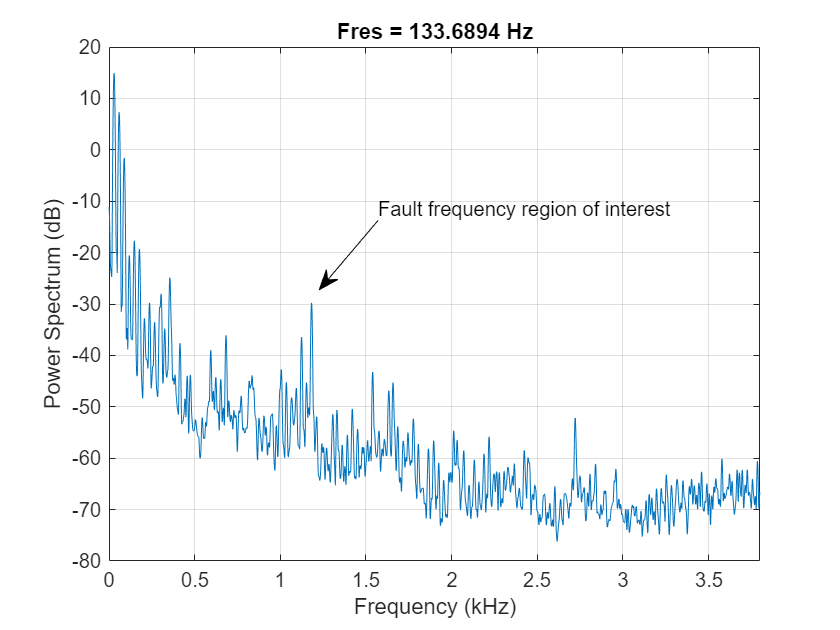

% Power spectrum of vibration signal, Vib_acpi
vib = T.Vib_acpi{1};
pspectrum(vib.Data, Fs_vib);
annotation("textarrow", [0.45 0.38], [0.65 0.54], "String", "Fault frequency region of interest")

The envelope of signals after band-pass filtering them can help reveal demodulated signals containing behavior related to the health of the system.

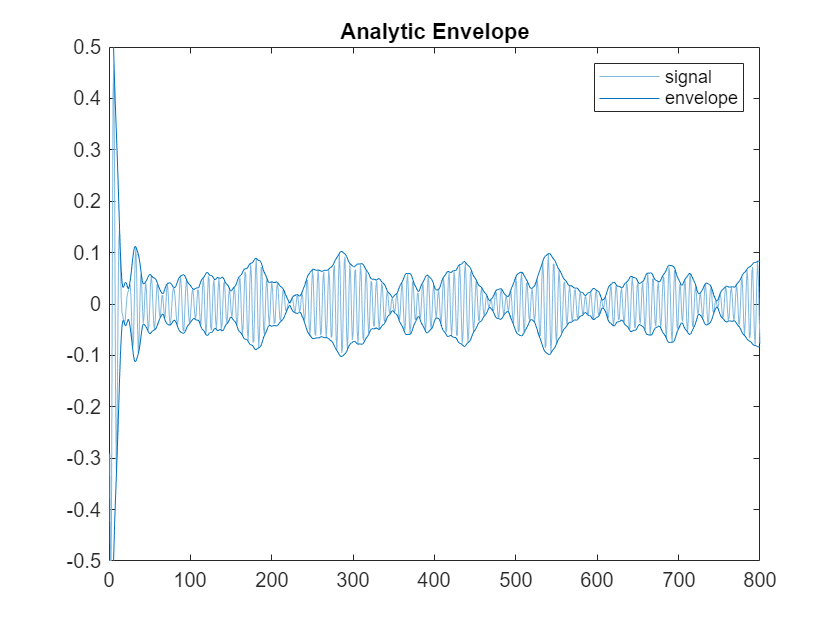

% Envelop of vibration signal
y = bandpass(vib.Data, [900 1300], Fs_vib);
envelope(y)
axis([0 800 -0.5 0.5])

## Supporting Functions

The `WriteToMemberFcn` property of the `fileEnsembleDatastore` object stores the handle of the function responsible for adding new data to each member of the ensemble. The **Diagnostic Feature Designer** app uses this function to save new processed data and extracted features.

function writeMemberData(filename, data)
% Write data into the fileEnsembleDatastore.
%
% Inputs:
%  filename - a string for the file name to write
%  data     - a data structure to write to the file

% Save fields as individual variables.
save(filename, '-append', '-struct', 'data');
end

The function stored in the `ReadFcn` property of the `fileEnsembleDatastore` object reads member data from ensemble member files. The **Diagnostic Feature Designer** app uses this function to read signals, spectra, and features. You can also use this function to create synthetic signals on the fly that can be used in the app.

function T = readMemberData(filename, variables)
% Read variables from a fileEnsembleDatastore
%
% Inputs:
%  filename  - file to read, specified as a string
%  variables - variable names to read, specified as a string array
%              Variables must be a subset of SelectedVariables specified in
%              the fileEnsembleDatastore.
% Output:
%  T         - a table with a single row

mfile = matfile(filename); % Allows partial loading

% Read condition variables directly from the top-level structure fields
T = table();
for i = 1:numel(variables)
  var = variables(i);

  switch var
    case {'Health', 'Load'}
      % Condition variables
      val = mfile.(var);
    case {'Va', 'Vb', 'Vc', 'Ia', 'Ib', 'Ic'}
      % Electrical signals
      val = getSignal(mfile, var, mfile.Fs_elec);
    case {'Vib_acpi', 'Vib_carc', 'Vib_acpe', 'Vib_axial', 'Vib_base', 'Trigger'}
      % Vibration signals
      val = getSignal(mfile, var, mfile.Fs_vib);
    case {'Vib_acpi_env'}
      % Synthetic envelope signals for vibration data
      sig = regexprep(var, '_env', '');
      TT = getSignal(mfile, sig, mfile.Fs_vib);
      % Envelope of band-pass filtered signal
      y = bandpass(TT.Data, [900 1300], mfile.Fs_vib);
      yUpper = envelope(y);
      val = timetable(yUpper, 'VariableNames', "Data", 'RowTimes', TT.Time);
    case {'Ia_env'}
      % Synthetic envelope signals for electrical data
      sig = regexprep(var, '_env', '');
      TT = getSignal(mfile, sig, mfile.Fs_elec);
      % Envelope of band-pass filtered signal
      y = bandpass(TT.Data, [900 1300], mfile.Fs_elec);
      yUpper = envelope(y);
      val = timetable(yUpper, 'VariableNames', "Data", 'RowTimes', TT.Time);
    case {'Ia_env_ps'}
      % Synthetic envelope spectra for electrical data
      sig = regexprep(var, '_env_ps', '');
      TT = getSignal(mfile, sig, mfile.Fs_elec);
      % Envelope spectrum of band-pass filtered signal
      [ES,F] = envspectrum(TT, 'Method', 'hilbert', 'Band', [900 1300]);
      val = [F,ES];
    otherwise
      % Other features and signals.
      val = mfile.(var);
  end

  if numel(val) > 1
    val = {val};
  end

  % Add the data to the output table, using the variable name.
  T.(var) = val;
end
end

When the original signal is longer than what is needed to extract useful features from it, you can use the following helper function to extract a shorter portion of the full signal from the member data.

function TT = getSignal(mfile, signame, Fs)
% Extract a 1.0 second portion of the signal after 10 seconds of measurements.
signame = char(signame);
n = size(mfile, signame, 1);
t = (0:n-1)' / Fs;
I = find((t >= 10.0) & (t <= 11.0)); % 1.0 sec of data
TT = timetable(mfile.(signame)(I,1), 'VariableNames', "Data", 'RowTimes', seconds(t(I)));
end

## References

- Treml, Aline Elly, Rogério Andrade Flauzino, Marcelo Suetake, and Narco Afonso Ravazzoli Maciejewski. "Experimental database for detecting and diagnosing rotor broken bar in a threephase induction motor." IEEE Dataport, updated September 24, 2020, [https://dx.doi.org/10.21227/fmnm-bn95](https://dx.doi.org/10.21227/fmnm-bn95).

*Copyright 2022-2023 The MathWorks, Inc.*